# Conversions

inch2m = 1/39.37;
bar2Pa = 100000;

# Task 1.1: Theoretical Mach number variation along working section 

## Interpolating the wind tunnel liner dimensions

Interpolation is necessary to align the points on both sections of the aerofoil. Later calculations will require consistent, matching point numbering. The values will also be converted to SI units from Imperial units.

topSurface_inches = readtable("Work\aerofoil-surface-dimensions.xlsx","Sheet","Top Surface")

topSurface_inches = 54×2 table
    x__inches_    y__1___inches_
    __________    ______________

          0            0.42     
       0.29           0.576     
       0.67           0.782     
      1.055           0.985     
       1.44           1.175     
       1.82           1.357     
      2.205           1.535     
       2.59           1.706     
      2.975           1.862     
      3.355           2.001     
       3.74           2.122     
      4.125            2.22     
       4.51           2.299     
       4.89           2.363     
      5.275           2.414     
       5.66           2.454     


bottomSurface_inches = readtable("Work\aerofoil-surface-dimensions.xlsx",Sheet="Bottom Surface")

bottomSurface_inches = 21×2 table
    x__inches_    y__2___inches_
    __________    ______________

          0            0.42     
      0.125           0.485     
       0.25           0.546     
      0.375           0.602     
        0.5           0.653     
      0.625           0.701     
       0.75           0.745     
      0.875           0.786     
          1           0.822     
      1.125           0.855     
       1.25           0.884     
      1.375            0.91     
        1.5           0.933     
      1.625           0.952     
       1.75           0.968     
      1.875           0.981     



topSurfaceArray_inches = table2array(topSurface_inches);
bottomSurfaceArray_inches = table2array(bottomSurface_inches);

% Inerpolating the bottom surface's y-coordinate points relative to the top surface's x-coordinates.
bottom_interp = interp1(bottomSurfaceArray_inches(:,1),bottomSurfaceArray_inches(:,2),topSurfaceArray_inches(:,1),"linear");

% Assembling the completed array, in inches
bottomSurfaceInterp_inches = [topSurfaceArray_inches(:,1) bottom_interp];

% Converting all matrices to S.I. units
bottomSurface = bottomSurfaceInterp_inches*inch2m;
topSurface = topSurfaceArray_inches*inch2m;

% Creating tables
bottomSurafce_table = array2table(bottomSurface);
bottomSurafce_table.Properties.VariableNames = {'x_metres' 'y_metres'};
topSurface_table = array2table(topSurface);
topSurface_table.Properties.VariableNames = {'x_metres' 'y_metres'};
bottomSurafce_table

bottomSurafce_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366    0.014324
    0.017018    0.018208
    0.026797    0.021248
    0.036576    0.023418
    0.046228    0.024772
    0.056007    0.025363
    0.065786      0.0254
    0.075565      0.0254
    0.085217      0.0254
    0.094996      0.0254
     0.10478      0.0254
     0.11455      0.0254
     0.12421      0.0254
     0.13399      0.0254
     0.14376      0.0254


topSurface_table

topSurface_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366     0.01463
    0.017018    0.019863
    0.026797    0.025019
    0.036576    0.029845
    0.046228    0.034468
    0.056007    0.038989
    0.065786    0.043332
    0.075565    0.047295
    0.085217    0.050826
    0.094996    0.053899
     0.10478    0.056388
     0.11455    0.058395
     0.12421     0.06002
     0.13399    0.061316
     0.14376    0.062332


## Plotting the Coordinates

Before plotting, the values must be corrected to show how they vary along the section. To do this, the centre of the wind tunnel(3 inches of its diameter) will be used as a reference point. The coordinates will then be added or subtracted to the constant 3, in order to show how the section varies. See the plot below for a better understanding of what this means.

% Finding the coordiantes of the top and bottom liners relative to the
% centre of the wind tunnel
bottomSurfacre_ycoord_relative = -3*inch2m + bottomSurface(:,2);
topSurface_ycoord_relative = 3*inch2m - topSurface(:,2);

bottomSurface_relative = [bottomSurface(:,1) bottomSurfacre_ycoord_relative]

bottomSurface_relative =          0   -0.0655
    0.0074   -0.0619
    0.0170   -0.0580
    0.0268   -0.0550
    0.0366   -0.0528
    0.0462   -0.0514
    0.0560   -0.0508
    0.0658   -0.0508
    0.0756   -0.0508
    0.0852   -0.0508


topSurface_relative = [topSurface(:,1) topSurface_ycoord_relative]

topSurface_relative =          0    0.0655
    0.0074    0.0616
    0.0170    0.0563
    0.0268    0.0512
    0.0366    0.0464
    0.0462    0.0417
    0.0560    0.0372
    0.0658    0.0329
    0.0756    0.0289
    0.0852    0.0254


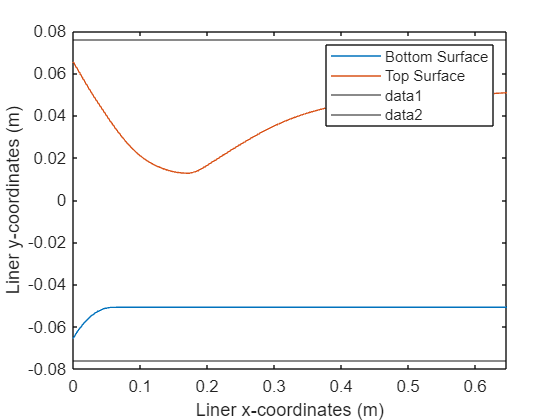


plot(bottomSurface_relative(:,1),bottomSurface_relative(:,2))
hold on
plot(topSurface_relative(:,1),topSurface_relative(:,2))
legend("Bottom Surface", "Top Surface")
xlabel("Liner x-coordinates (m)")
ylabel("Liner y-coordinates (m)")
yline(3*inch2m)
yline(-3*inch2m)
xlim([0 max(topSurface_relative(:,1))])
hold off

## Plotting the variation of the Mach number

To accomplish this, the ratio of the local area to the area at the throat is needed. This ratio shows how the mach number varies through the wind tunnel, as pressure, area and velocity(and by extension mach number) are all related. As pressure increases due to a decrease in area, the velocity of the free stream air must also decrease. With this in mind, we can assume that the velocity - and therefore mach number - is at its lowest when at the throat, and at its highest elsewhere. We can then use this assumption and set the throat as a refenrence point to see how much larger the mach number will be in sections of the wind tunnel with larger areas. In theory, the mach number should not be lower than one, as that would suggest that the throat does not have the smallest area. The  

throatRadius = ( min(topSurface_relative(:,2)) - max(bottomSurface_relative(:,2)) )/2;
throatArea = pi*throatRadius^2

throatArea = 0.0032


localRadius = ( topSurface_relative(:,2) - bottomSurface_relative(:,2) )./2;
localArea = pi*localRadius.^2

localArea =     0.0135
    0.0120
    0.0103
    0.0088
    0.0077
    0.0068
    0.0061
    0.0055
    0.0050
    0.0046


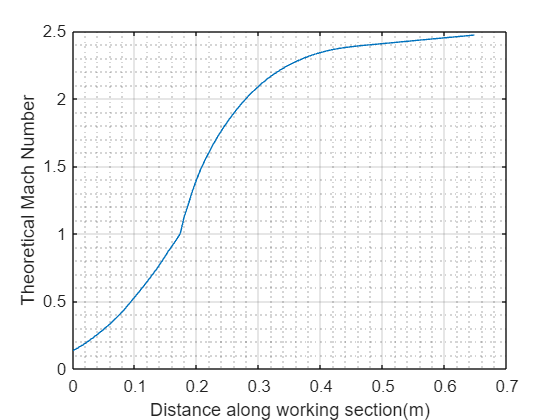


areaRatio = localArea/throatArea;
gamma = 1.4;

% this loop calculates the subsonic theoretical mach numbers of the wind
% tunnel using the newton raphson method
for j = 1:19 % the throat where mach =1  is at position 19
    M(1) = 0.2; % Initial subsonic mach number guess 
    Astar=areaRatio(j);
    for i = 1:1000
        f(i) = Astar.*M(i) - ( ( 1 + ( (gamma - 1)/2 ).*(M(i))^2 )/( (gamma + 1)/2 ) )^( (gamma + 1)/(2*(gamma - 1)) );
        df(i) = Astar - M(i).*( ( 1 + ((gamma - 1)/2).*(M(i))^2 )/( (gamma+1)/2 ) )^( ( (gamma + 1)/(2*(gamma - 1)) )- 1 );
        M_new(j) = M(i) - f(i)./df(i); % Calcuates the new mach number 
        if abs(M_new-M(i)) < 1e-20 % compares the difference in mach number to a specified tolerance 
            break 
        end  
           i=i+1;
           M(i) = M_new(j); % Makes the new mach number the starting point for the next interation 
    end
    j=j+1;
end

% this loop calculates the supersonic theoretical mach numbers of the wind
% tunnel using the newton raphson method
for j = 20:length(areaRatio) % the throat where mach =1  at position 19
    M(1) = 1.8; % Initial guess for supersonic mach number 
    Astar=areaRatio(j);
    for i = 1:1000
        f(i) = Astar.*M(i) - ( ( 1 + ( (gamma - 1)/2 ).*(M(i))^2 )/( (gamma + 1)/2 ) )^( (gamma + 1)/(2*(gamma - 1)) );
        df(i) = Astar - M(i).*( ( 1 + ((gamma - 1)/2).*(M(i))^2 )/( (gamma+1)/2 ) )^( ( (gamma + 1)/(2*(gamma - 1)) )- 1 );
        M_new(j) = M(i) - f(i)./df(i); % Calcuates the new mach number 
        if abs(M_new-M(i)) < 1e-20 % compares the difference in mach number to a specified tolerance 
            break 
        end  
           i=i+1;
           M(i) = M_new(j); % Makes the new mach number the starting point for the next interation 
    end
    j=j+1;
end

plot(bottomSurface(:,1),M_new)
xlabel("Distance along working section(m)")
ylabel("Theoretical Mach Number")
grid on
grid minor

# Task 1.2: WT measured pressure ratio and Mach number along working section at two test conditions

The wind tunnel is run at 2 different pressures - 150psi and 75psi- these are the 2 conditions under which the working section is tested. 

### Preparing the raw data

The provided data has been given in text format and cannot easily be converted to a readable spreadsheet. To achieve a usable tabular format, the data will need to be split into individual elements and the reassembeled into a usable table/array. The following will be my attempt at accomplishing this using the knowledge from py4e.

% Loading the data into MATLAB
supersonic150_psi = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonic150Psi.txt");
supersonic75_psi = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonick75Psi.txt");
supersonicUncertaintity = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\Uncertainty.txt")

supersonicUncertaintity = 7×1 string array
    "Observation from experment"
    ""
    "Barometric pressure smallest unit: 10Pa"
    ""
    "VDAS Pressure Tapping smallest unit: 0.001 Bar"
    ""
    "[i.e. the above data are not the uncertainties but precision]"


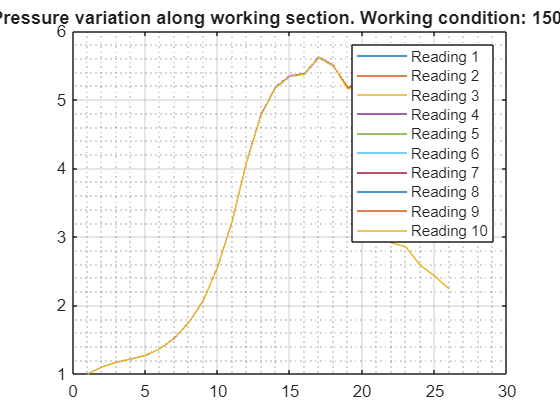

p_atm = 98910;
%% Supersonic data at 150 psi

    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic150_psi);
    
    % Defining the new array to be assembled
    supersonic150_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic150_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic150_PSI_tab = array2table(supersonic150_PSI);
    supersonic150_PSI_tab(1,:) = [];
    
    supersonic150_PSI_tab.Properties.VariableNames = columnNames;

%% Supersonic data at 75 psi


    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic75_psi);
    
    % Defining the new array to be assembled
    supersonic75_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic75_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );             % converting the pressures from bar to Pa
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic75_PSI_tab = array2table(supersonic75_PSI);
    supersonic75_PSI_tab(1,:) = [];
    
    supersonic75_PSI_tab.Properties.VariableNames = columnNames;

%% Converting from bar to Pa

    supersonic75_PSI_array = str2double( table2array( supersonic75_PSI_tab(:,2:end-1) ) );
    supersonic75_PSI_pascals_array = p_atm + supersonic75_PSI_array(:,2:26).*bar2Pa + 269;

    supersonic150_PSI_array = str2double( table2array( supersonic150_PSI_tab(:,2:end-1) ) );
    supersonic150_PSI_pascals_array = p_atm + supersonic150_PSI_array*bar2Pa + 269;

    % Assembling tables of the converted values
    supersonic150_PSI_pascals_tab = [supersonic150_PSI_tab(:,1)];
    supersonic150_PSI_pascals_tab = horzcat( supersonic150_PSI_pascals_tab,array2table(supersonic150_PSI_pascals_array) );
    % supersonic150_PSI_pascals_tab.Properties.VariableNames = columnNames

    supersonic75_PSI_pascals_tab = [supersonic75_PSI_tab(:,1)];
    supersonic75_PSI_pascals_tab = horzcat( supersonic75_PSI_pascals_tab,array2table(supersonic75_PSI_pascals_array) );
    % supersonic75_PSI_pascals_tab.Properties.VariableNames = columnNames

%% Finding the pressure ratios (P_0/P)
% For the 150psi working condition
pressureRatio_150_plot = [ supersonic150_PSI_pascals_array(:,1)./supersonic150_PSI_pascals_array(:,1) supersonic150_PSI_pascals_array(:,1)./supersonic150_PSI_pascals_array(:,2:26) ];
xaxisValues = 1:26;                                                                                             % the pressure tap numbers
plot(xaxisValues,pressureRatio_150_plot')
grid on
grid minor
legend('Reading 1', 'Reading 2', 'Reading 3', 'Reading 4', 'Reading 5', 'Reading 6', 'Reading 7', 'Reading 8', 'Reading 9', 'Reading 10')
title('Pressure variation along working section. Working condition: 150psi')

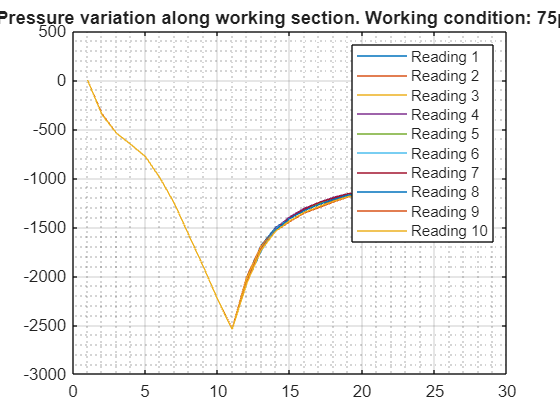




% % For the 75psi working condition
% pressureRatio_75_plot = [ supersonic75_PSI_pascals_array(:,1)./supersonic75_PSI_pascals_array(:,1) supersonic75_PSI_pascals_array(:,2:26)/supersonic75_PSI_pascals_array(:,1) ]
plot(xaxisValues,pressureRatio_75_plot')
grid on
grid minor
legend('Reading 1', 'Reading 2', 'Reading 3', 'Reading 4', 'Reading 5', 'Reading 6', 'Reading 7', 'Reading 8', 'Reading 9', 'Reading 10')
title('Pressure variation along working section. Working condition: 75psi')


$$\frac{p_0}{p} = \big[ 1 + \frac{\gamma - 1}{2} M^2 \big]^{ \frac{ \gamma }{ \gamma -1 } }

\\

M = \sqrt{ \frac{ \bigg[ \bigg( \frac{p_0}{p} \bigg)^{ \frac{ \gamma -1 }{ \gamma } } - 1 \bigg] }{ \frac{ \gamma - 1 }{2} } } $$


%% Finding the mach numbers using the presure ratios
% For the 150psi working condition
mach_150_plot = pressureRatio_150_plot.^0.2857

mach_150_plot =     1.0000    1.0288    1.0461    1.0577    1.0706    1.0936    1.1268    1.1737    1.2302    1.3081    1.3974    1.4953    1.5634    1.5996    1.6141    1.6166    1.6372    1.6268    1.5972    1.6068    1.5787    1.4716    1.6242    1.5996    1.4216    1.3654
    1.0000    1.0288    1.0461    1.0577    1.0706    1.0941    1.1268    1.1737    1.2302    1.3081    1.3974    1.4953    1.5634    1.5996    1.6141    1.6166    1.6372    1.6268    1.5972    1.6068    1.5787    1.4716    1.6242    1.5996    1.4330    1.3724
    1.0000    1.0288    1.0461    1.0577    1.0706    1.0941    1.1268    1.1737    1.2302    1.3081    1.3974    1.4953    1.5634    1.5996    1.6141    1.6166    1.6372    1.6268    1.5972    1.6068    1.5787    1.4716    1.6242    1.5996    1.4541    1.3773
    1.0000    1.0291    1.0464    1.0580    1.0710    1.0939    1.1271    1.1740    1.2305    1.3085    1.3978    1.4958    1.5638    1.6000    1.6146    1.6171    1.6377    1.6272    1.5976    1.6072 


% For the 75psi working condition
mach_75_plot = sqrt( 2*( (pressureRatio_75_plot).^( (gamma - 1)/gamma ) - 1 )/(gamma-1) )

mach_75_plot =    0.0000 + 0.0000i   4.2019 + 2.4701i   4.5394 + 2.6018i   4.6890 + 2.6614i   4.8249 + 2.7161i   5.0236 + 2.7972i   5.2183 + 2.8776i   5.4160 + 2.9602i   5.5793 + 3.0290i   5.7277 + 3.0920i   5.8442 + 3.1417i   5.6306 + 3.0507i   5.4741 + 2.9846i   5.3739 + 2.9425i   5.3141 + 2.9175i   5.2602 + 2.8950i   5.2183 + 2.8776i   5.1850 + 2.8638i   5.1505 + 2.8495i   5.1369 + 2.8439i   5.1341 + 2.8427i   5.1341 + 2.8427i   5.1286 + 2.8405i   5.1314 + 2.8416i   5.1314 + 2.8416i   5.1341 + 2.8427i
   0.0000 + 0.0000i   4.2019 + 2.4701i   4.5394 + 2.6018i   4.6890 + 2.6614i   4.8249 + 2.7161i   5.0236 + 2.7972i   5.2183 + 2.8776i   5.4160 + 2.9602i   5.5793 + 3.0290i   5.7277 + 3.0920i   5.8442 + 3.1417i   5.6306 + 3.0507i   5.4760 + 2.9854i   5.3846 + 2.9470i   5.3322 + 2.9251i   5.2793 + 2.9030i   5.2407 + 2.8869i   5.2005 + 2.8702i   5.1665 + 2.8561i   5.1451 + 2.8472i   5.1451 + 2.8472i   5.1451 + 2.8472i   5.1396 + 2.8450i   5.1396 + 2.8450i   5.1423 + 2.8461i   5.1396 + 2.8

# Task 1.3: Theoretical Mach number at different regimes, shock and expansion fan angles compared with WT measurements

To find the theoretical mach number, the Newton-Raphson method will be used. Following the guidance provided on blackboard, the area ratio and a relationship derived from that formula can be used to 'predict' the mach number